Solucion del siguiente sistema a través del metodo optimizado de desposición de Adomian, se tiene la siguiente ecuación


$$u_t + uu_x = x$$



$$u(x,0)=u_0=2, \;\;\;\;\;\; 0 \leq x \leq 3$$


Despues de realizar el algebra correspondiente, obtenemos la siguiente ecuación de recursión


$$u_{n+2} = (1+h) \int_0^t \frac{\partial u_{n+1}}{\partial t} dt + h \int_0^t A_{n+1} dt$$


Para este problema, el polinomio de Adomian esta dado por


$$A_n = \sum_{i=0}^n u_i u_{{n-i},x}$$


Ademas, obtuvimos que


$$u_1=-hxt, \;\; A_0 = 0$$


Ingresamos el codigo para calcular los polinomios de adomian, iniciamos definiendo u0

syms x t u h;
u=[2, -h*t*x];
a1=adomian(u,1,x);

Vamos a crear una funcion para calcular automaticante los polinomios de la funcion u a traves de la ecuación recursiva

u2=recurrencia(u,a1,2,t,h);
u=cat(2,u,u2);

Calculamos varios $u_n$, u3

a2=adomian(u,2,x);
u3=recurrencia(u,a2,3,t,h);
u=cat(2,u,u3);

u4

a3=adomian(u,3,x);
u4=recurrencia(u,a3,4,t,h);
u=cat(2,u,u4);

u5

a4=adomian(u,4,x);
u5=recurrencia(u,a4,5,t,h);
u=cat(2,u,u5);

u6

a5=adomian(u,5,x);
u6=recurrencia(u,a5,6,t,h);
u=cat(2,u,u6);

u7

a6=adomian(u,6,x);
u7=recurrencia(u,a6,7,t,h);
u=cat(2,u,u7);

u8

a7=adomian(u,7,x);
u8=recurrencia(u,a7,8,t,h);
u=cat(2,u,u8);

a8=adomian(u,8,x);
u9=recurrencia(u,a8,9,t,h);
u=cat(2,u,u9);

a9=adomian(u,9,x);
u10=recurrencia(u,a9,10,t,h);
u=cat(2,u,u10);

a10=adomian(u,10,x);
u11=recurrencia(u,a10,11,t,h);
u=cat(2,u,u11);

a11=adomian(u,11,x);
u12=recurrencia(u,a11,12,t,h);
u=cat(2,u,u12);

Ahora obtenemos el polinomio

u_calculada=0;
for i=1:length(u)
    u_calculada=u_calculada+u(i);
end
u_calculada

Procedemos a graficar, tomaremos un valor de x=2, y el valor de t va a variar desde 0.3 hasta 1.5

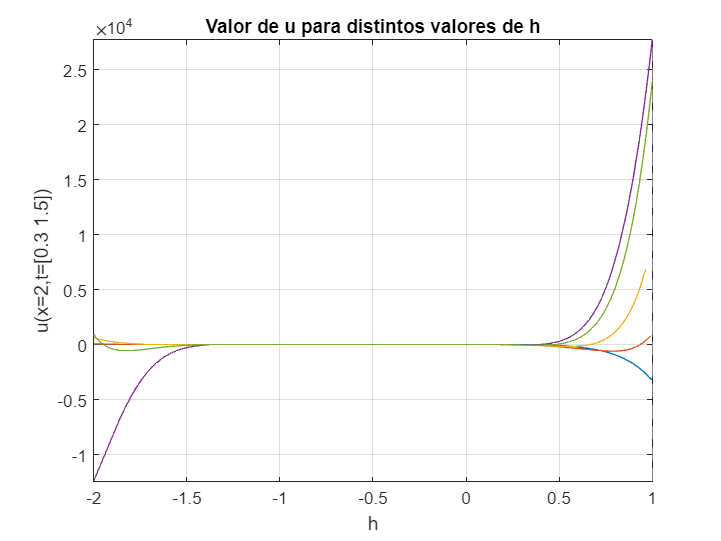

sustitucionx=subs(u_calculada,x,2);
sustituciont1=subs(sustitucionx,t,0.3);
sustituciont2=subs(sustitucionx,t,0.8);
sustituciont3=subs(sustitucionx,t,1);
sustituciont5=subs(sustitucionx,t,1.3);
sustituciont4=subs(sustitucionx,t,1.5);
figure
fplot(sustituciont1,[-2 1]);
hold on
fplot(sustituciont2,[-2 1]);
fplot(sustituciont3,[-2 1]);
fplot(sustituciont4,[-2 1]);
fplot(sustituciont5,[-2 1])
grid

title('Valor de u para distintos valores de h')
xlabel('h')
ylabel('u(x=2,t=[0.3 1.5])')

Ahora con estos datos calculamos el error, vemos el parametro de convergencia cerca de en el rango (-2,1)

term1=diff(u_calculada,t,1);
term2=u_calculada.*diff(u_calculada,x,1);
adentro=term1+term2-x;

aaa=expand(adentro^2);
int_primera=int(aaa,x,0,1);

int_segunda=int(int_primera,t,0,t);
a=sqrt(int_segunda);

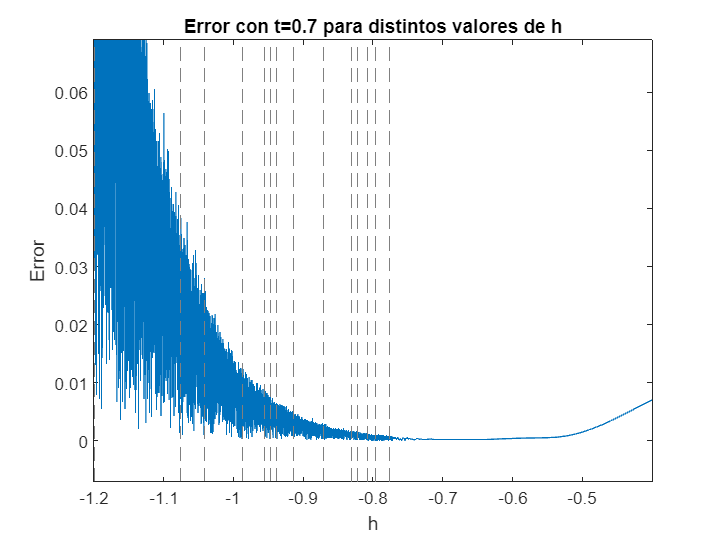

a1=subs(a,t,0.7);
figure
fplot(a1,[-1.2,-0.4])
title('Error con t=0.7 para distintos valores de h')
xlabel('h')
ylabel('Error')
ylim([-0.0069 0.0690])

Para este caso, con u=6, el error minimo esta en h=-0.99

Finalmente, tenemos que

u_final=subs(u_calculada,h,-1)

$$u\_final = \frac{540553\,t^{12}}{47900160}-\frac{1382\,x\,t^{11}}{155925}-\frac{50521\,t^{10}}{1814400}+\frac{62\,x\,t^{9}}{2835}+\frac{277\,t^{8}}{4032}-\frac{17\,x\,t^{7}}{315}-\frac{61\,t^{6}}{360}+\frac{2\,x\,t^{5}}{15}+\frac{5\,t^{4}}{12}-\frac{x\,t^{3}}{3}-t^{2}+x\,t+2$$